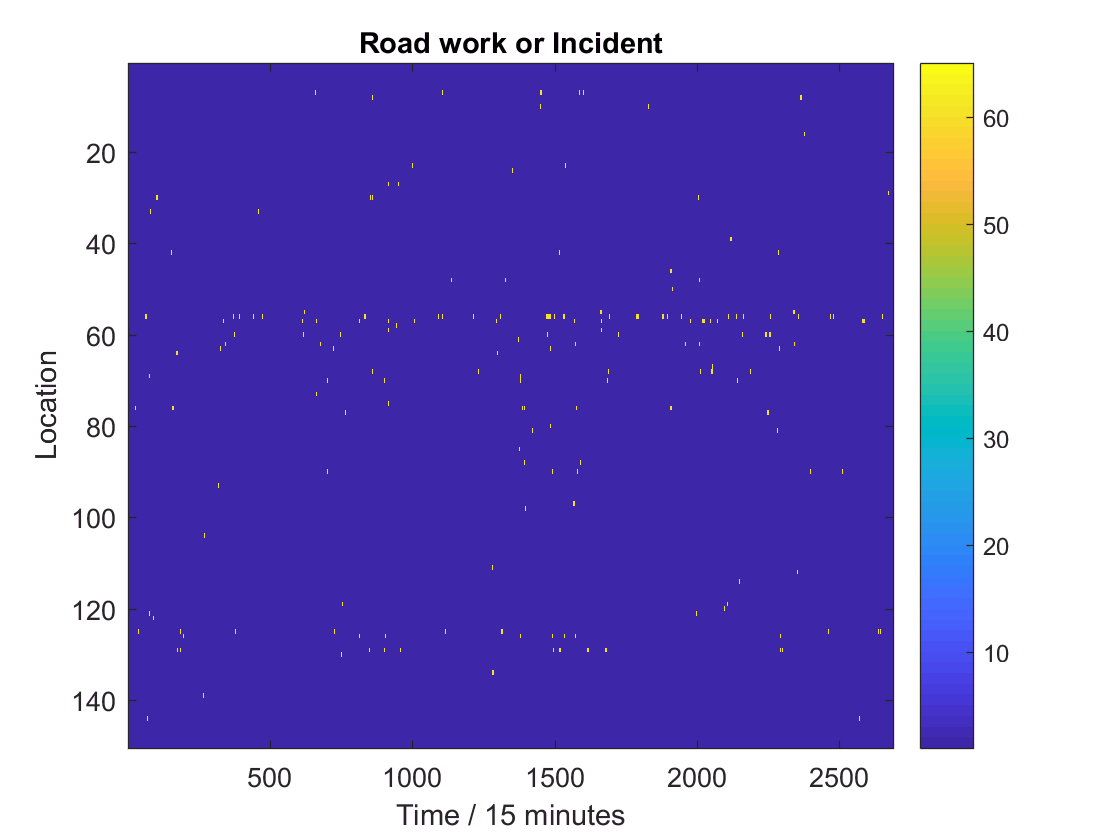

% This file contains the source code used in 
% Thomas Steffen, Gerwald Lichtenberg:
% A Machine Learning Approach to Traffic Flow Prediction using CP Tensor Decomposition
% IFAC 2020

% This code is written for MATLAB R2017a, 
% and it requires tensorlab 3.0 as publish at
% https://www.tensorlab.net/ .
% It is easy to adapt to use a different tensor toolbox. 

% T1 needs to contain the tensor data set, 
% as collected from http://webtris.highwaysengland.co.uk/
% This was a manual step, and it is not included here. 
% The expected size is 150x96x7x4, 
% but it should be easy to adapt this script to other sizes. 

% T1 = T(:,:,:,:,r);
% training set 
T1t = T1(:,:,:,1:2);
% verification set
T1v = T1(:,:,:,3:4);
clf;
image(reshape(T2,[150 96*28])*20);
xlabel('Time / 15 minutes');
ylabel('Location');
title('Road work or Incident');
colorbar;

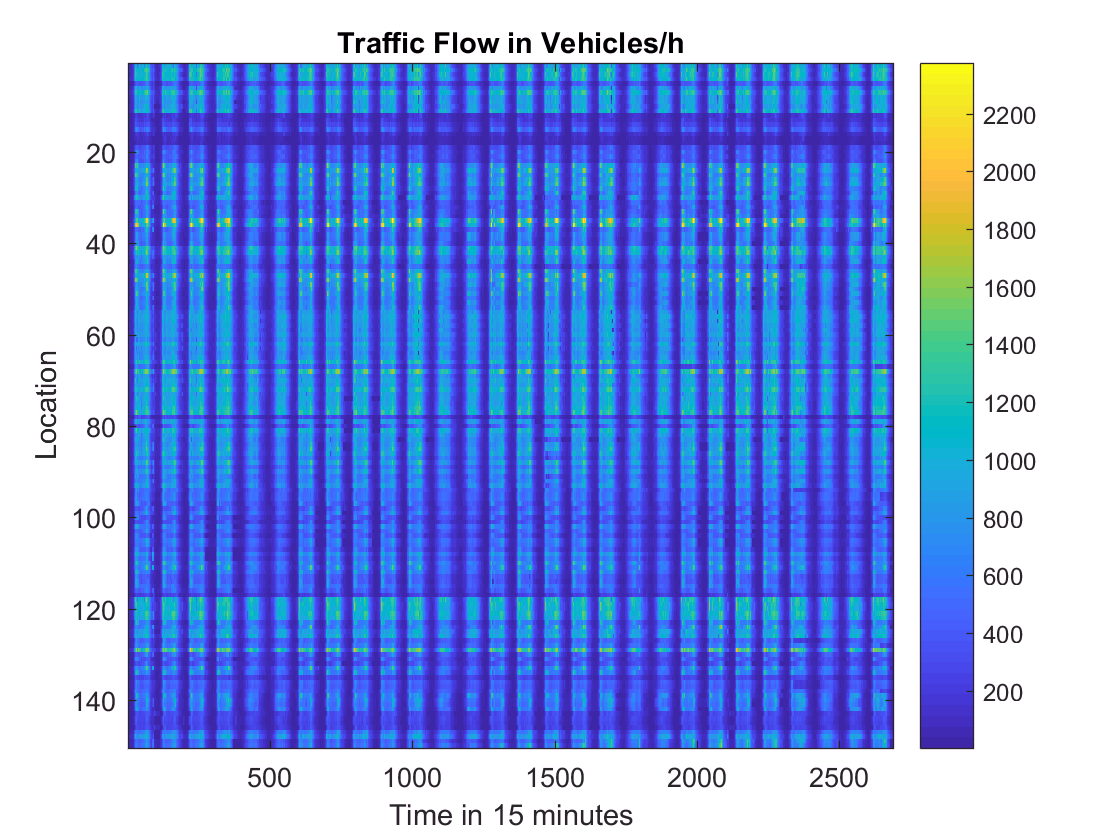


image(reshape(T1,[150 96*28]),'CDataMapping','scaled');
xlabel('Time in 15 minutes');
ylabel('Location');
title('Traffic Flow in Vehicles/h');
colorbar;

% CPD
n = 7;
[Tcpd,lambda,Tgen] = mycpd_TL(T1t,n);
mean(Tgen(:))

ans = 452.9971

Tcpd{4}=[Tcpd{4};mean(Tcpd{4},1);mean(Tcpd{4},1)];
Tcpdl = Tcpd;
Tcpdl{4}=Tcpdl{4}*diag(lambda);
Tgen = cpdgen(Tcpdl);
mean(Tgen(:))

ans = 452.9971

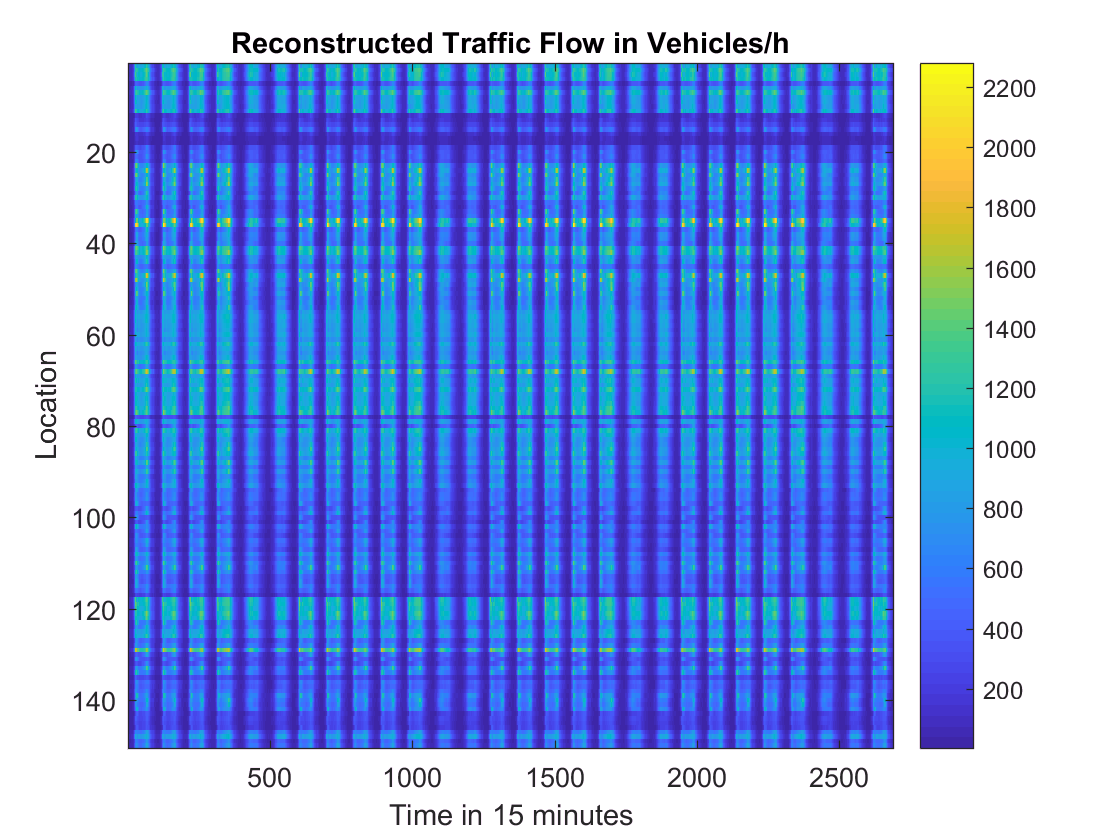

leg = cell(1,n);
for i=1:n
    leg{i} = num2str(lambda(i),5);
end

image(reshape(Tgen,[150 96*28]),'CDataMapping','scaled');
xlabel('Time in 15 minutes');
ylabel('Location');
title('Reconstructed Traffic Flow in Vehicles/h');
colorbar;

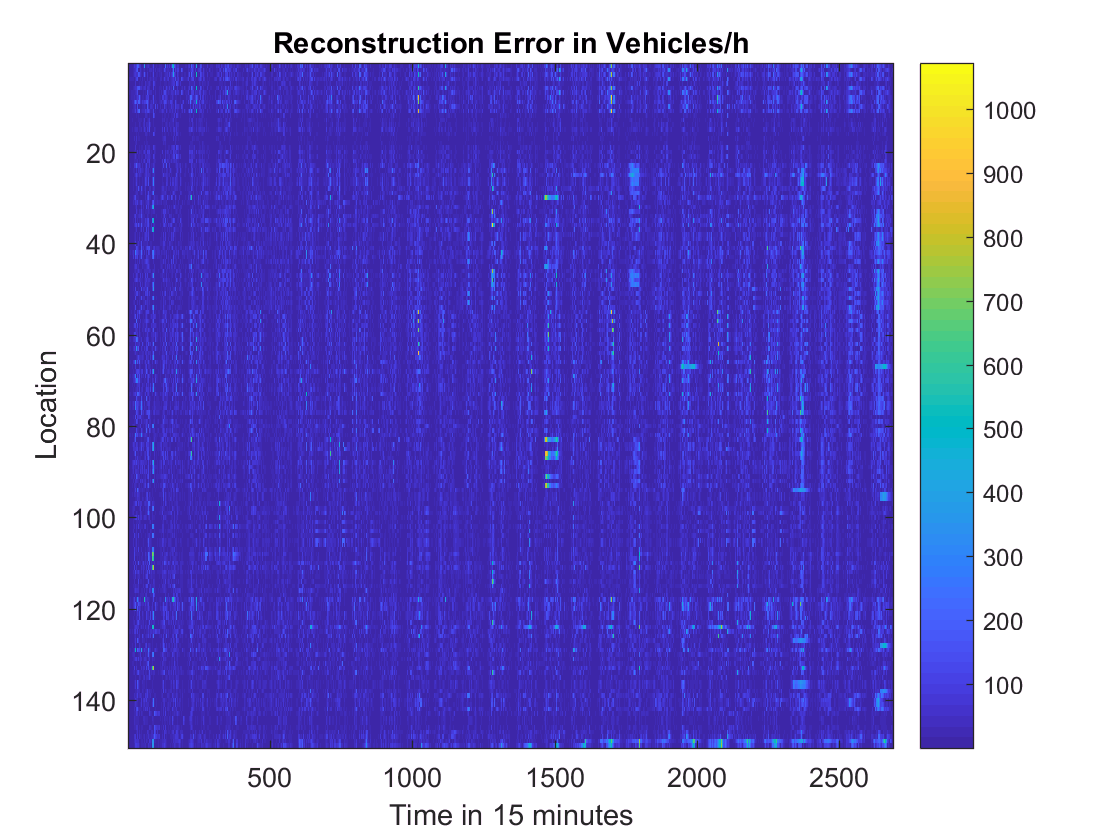

image(reshape(abs(T1-Tgen),[150 96*28]),'CDataMapping','scaled');
xlabel('Time in 15 minutes');
ylabel('Location');
title('Reconstruction Error in Vehicles/h');
colorbar;

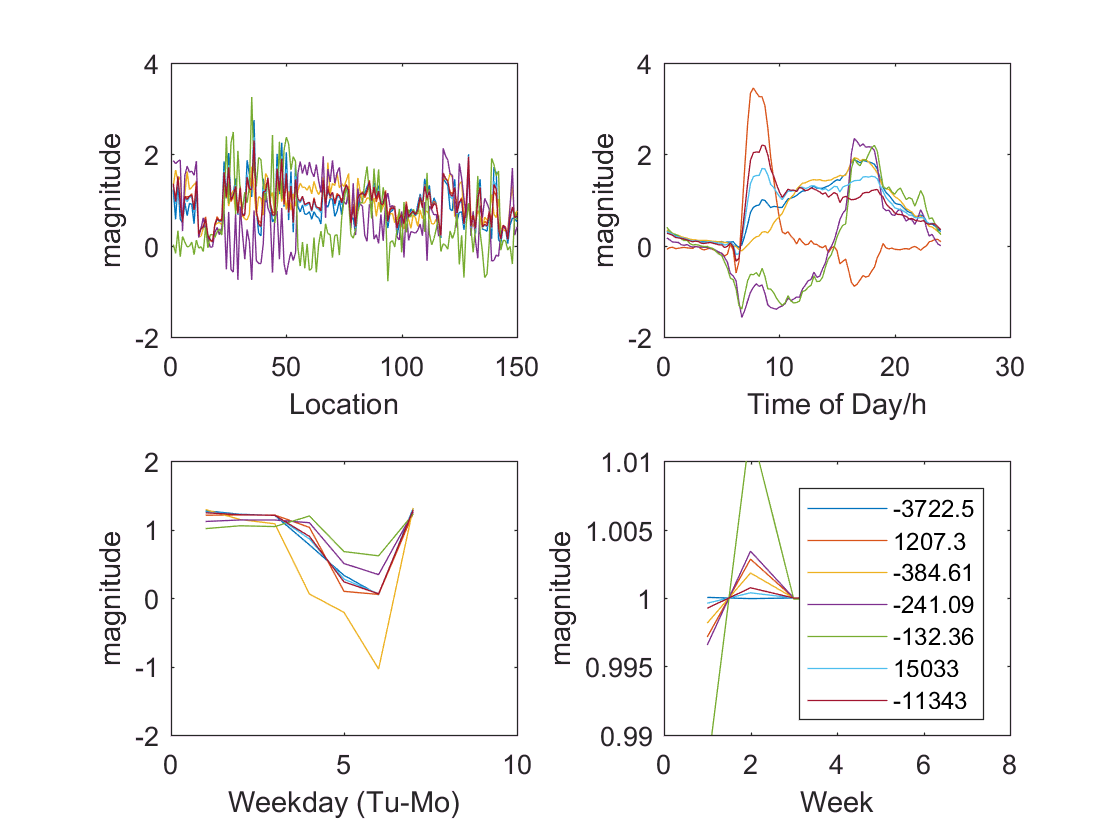


%% Plot the CPD
f = [1 0.25 1 1];
t = {'Location','Time of Day/h','Weekday (Tu-Mo)','Week'};
for i=1:4
    subplot(2,2,i);
    plot((1:size(Tcpd{i},1)).*f(i),Tcpd{i});
    xlabel(t{i});ylabel('magnitude');
end
axis([0 8 0.99 1.01]);
legend(leg);

%% Calculate a number of statistics

clf;

Tgen = cpdgen(Tcpdl);
Td = T1 - Tgen;
Td(isnan(Td)) = 0;
Tdelta = reshape(Td,[150*96*7 4]);

T2 = T1(:);
T2 = T2(~isnan(T2));

% Variation
[mean(T2.^2)
mean(Tgen(:).^2)]

ans =    1.0e+05 *

    3.5063
    3.4045


% RMSE squared

ans =    1.0e+03 *

    2.4569    2.7620    4.8346    5.6783


mean(Tdelta.^2)
%%
Tgen = mean(T1(:,:,:,1:2),4);
Tgen = Tgen(:,:,:,[1 1 1 1]);
Td = T1 - Tgen;
Td(isnan(Td)) = 0;
Tdelta = reshape(Td,[150*96*7 4]);

T2 = T1(:);
T2 = T2(~isnan(T2));

% Variation
[mean(T2.^2)
mean(Tgen(:).^2)]

ans =    1.0e+05 *

    3.5063
       NaN


mean(Tdelta.^2)

ans =    1.0e+03 *

    1.1762    1.1762    5.1725    6.0172


Tgen = cpdgen(Tcpdl);
Td = T1 - Tgen;
Td(isnan(Td)) = 0;
Tdelta = reshape(Td,[150*96*7 4]);

T2 = T1(:);
T2 = T2(~isnan(T2));

% Variation
[mean(T2.^2)
mean(Tgen(:).^2)]

ans =    1.0e+05 *

    3.5063
    3.4045


mean(Tdelta.^2)

ans =    1.0e+03 *

    2.4569    2.7620    4.8346    5.6783


## Correlation: original, time

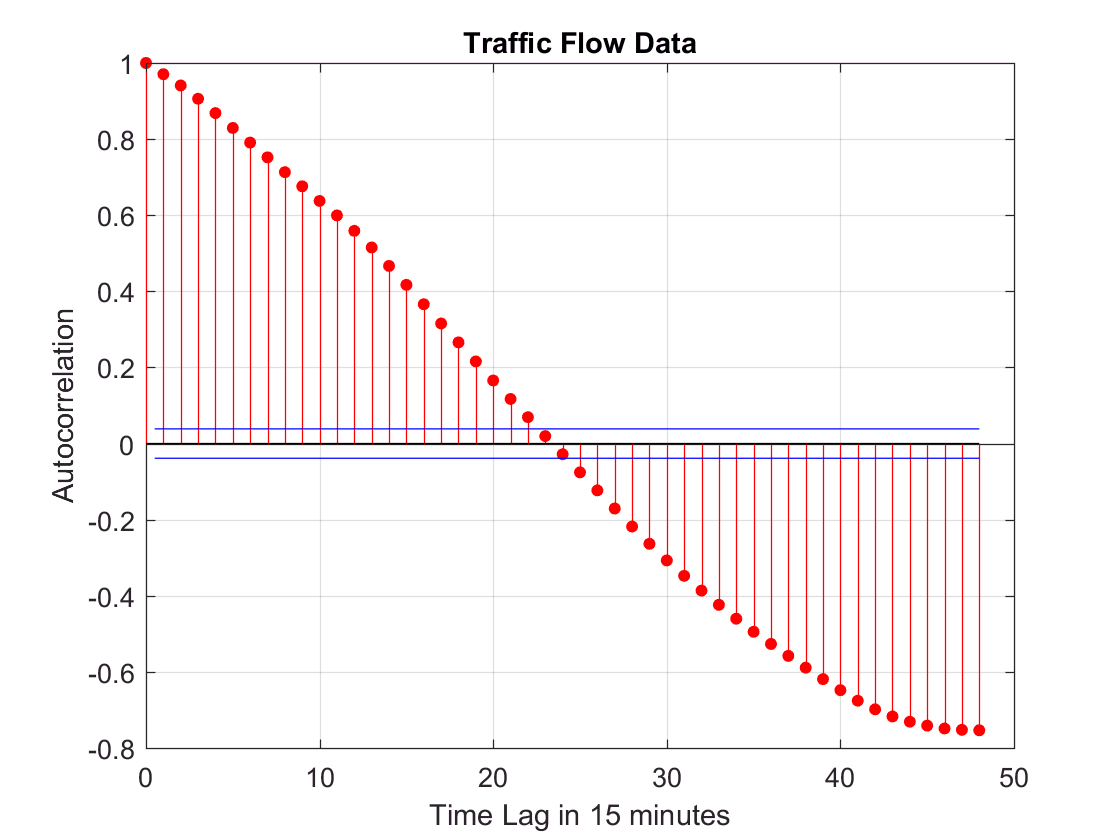

%%
l = 1;
T1l = T1(l,:,:,:);
T1l = T1l(:);
autocorr(T1l,4*12);
title('Traffic Flow Data');
ylabel('Autocorrelation');
xlabel('Time Lag in 15 minutes');

## Correlation: deviation, time

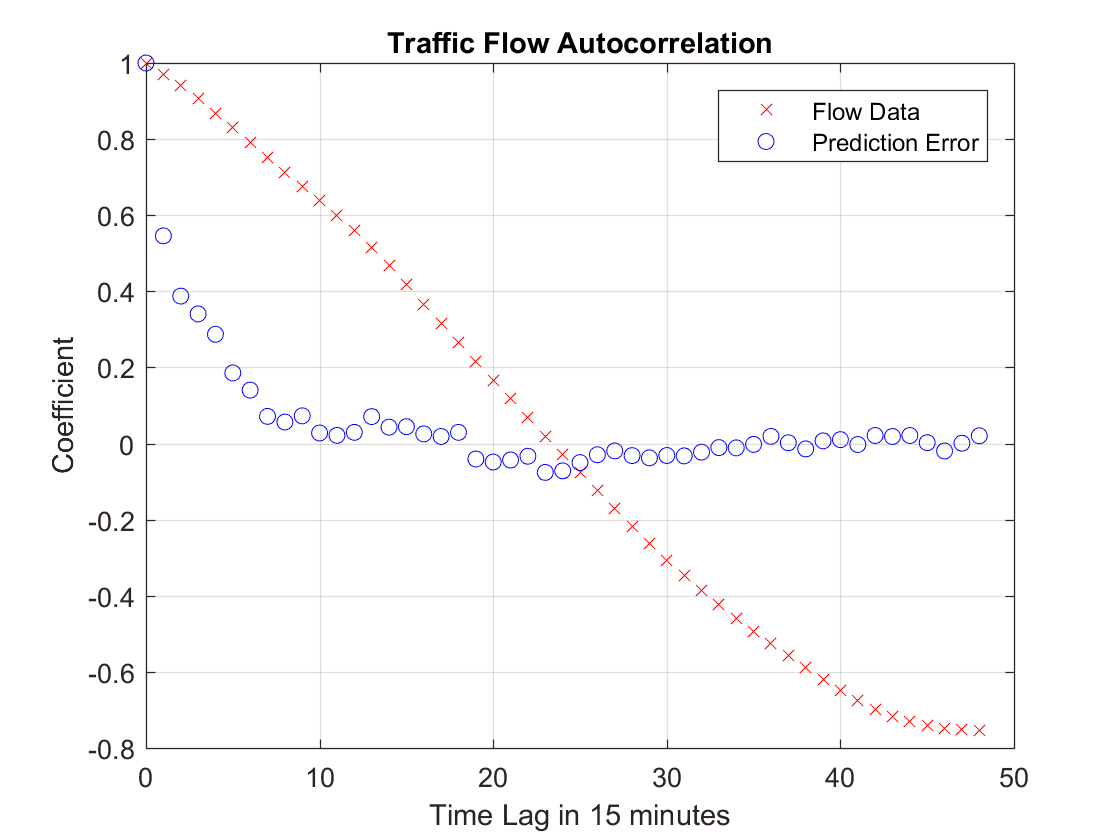

%%
l = 1;
Tdl = Td(l,:,:,3:4);
Tdl = Tdl(:);
a1=autocorr(T1l,4*12);
a2=autocorr(Tdl,4*12);
plot(0:48,a1,'xr',0:48,a2,'ob');
title('Traffic Flow Autocorrelation');
ylabel('Coefficient');
xlabel('Time Lag in 15 minutes');
legend('Flow Data','Prediction Error');
grid;

## Xcorr: deviation, time

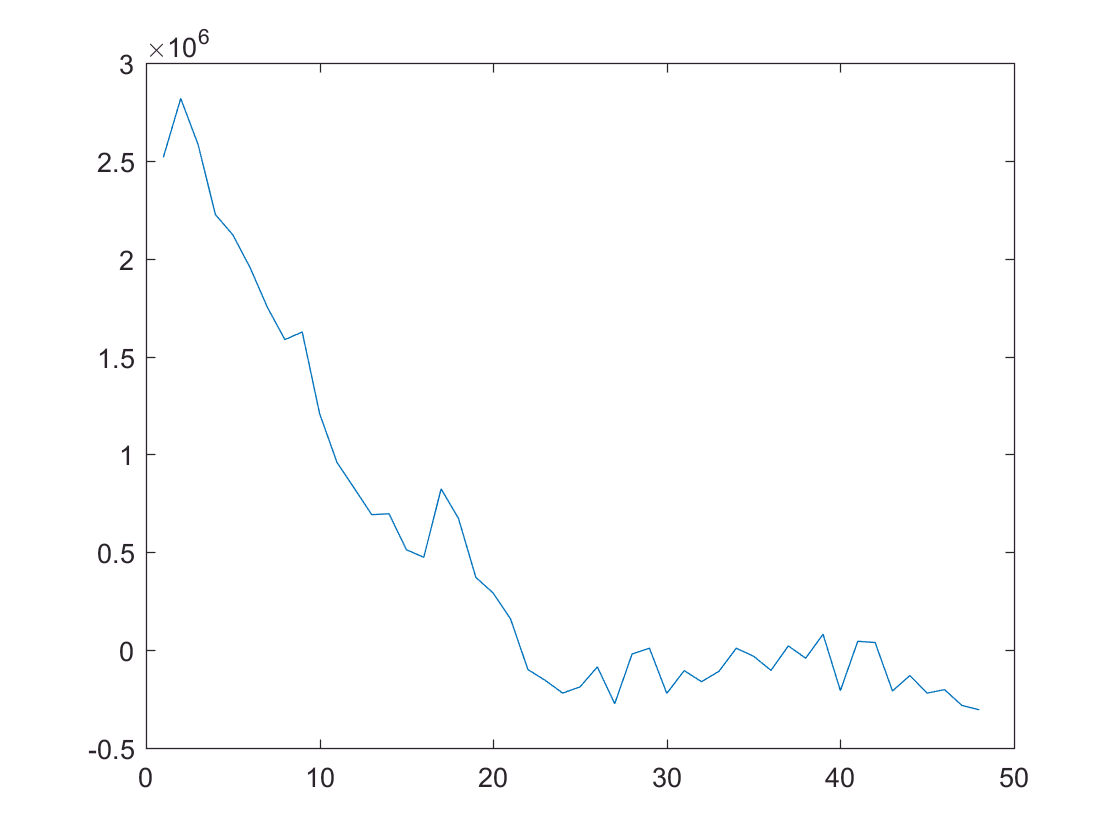

l = [1 10];
Tdl1 = Td(l(1),:,:,:);
Tdl2 = Td(l(2),:,:,:);
Tdl1 = Tdl1(:);
Tdl2 = Tdl2(:);
x=xcorr(Tdl1,Tdl2);
x=x((length(x)+1)./2:end,:);
plot(x(1:12*4));

## Corr: original, distance

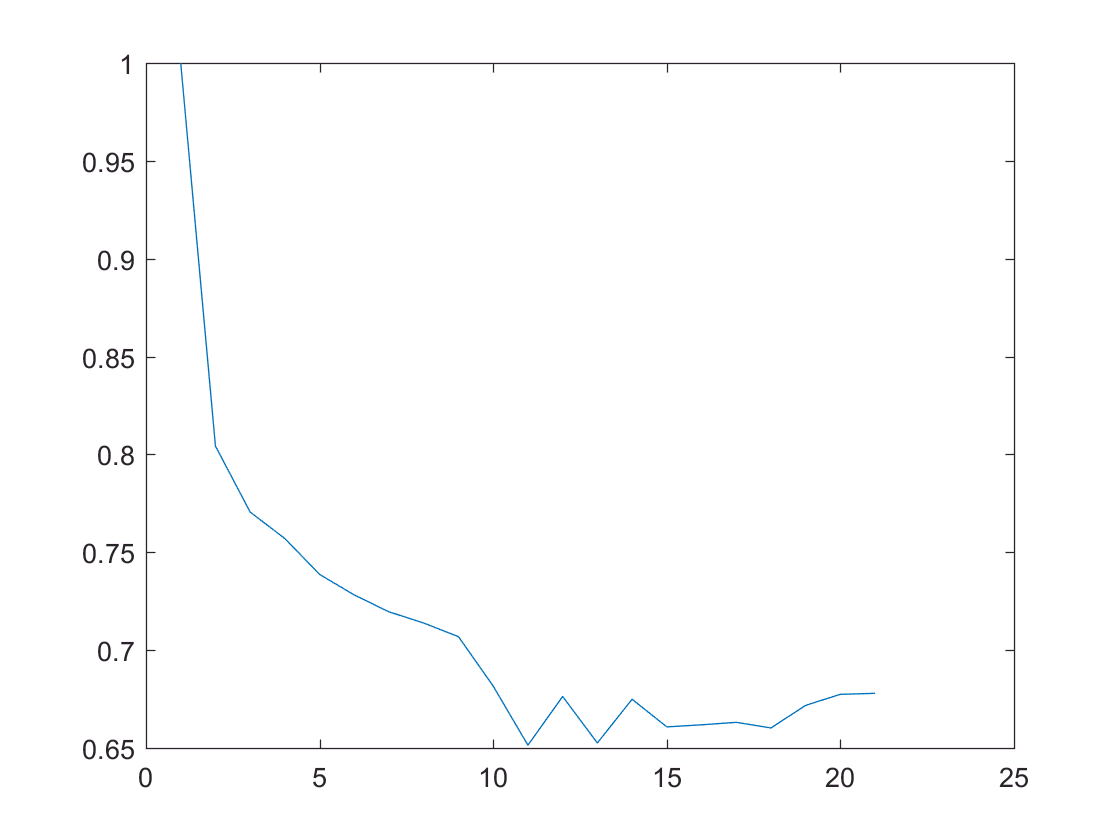

T1nonan = T1;
T1nonan(isnan(T1)) = 0;

l = 1;
Tdd = reshape(T1nonan,[150 96*7*4]);
c = nan(1,21);
for i=0:20
    a = Tdd(1:150-i,:);
    b = Tdd(1+i:150,:);
    cm = corrcoef(a,b);
    c(1+i) = cm(2);
end
plot(c);

## Wave plot

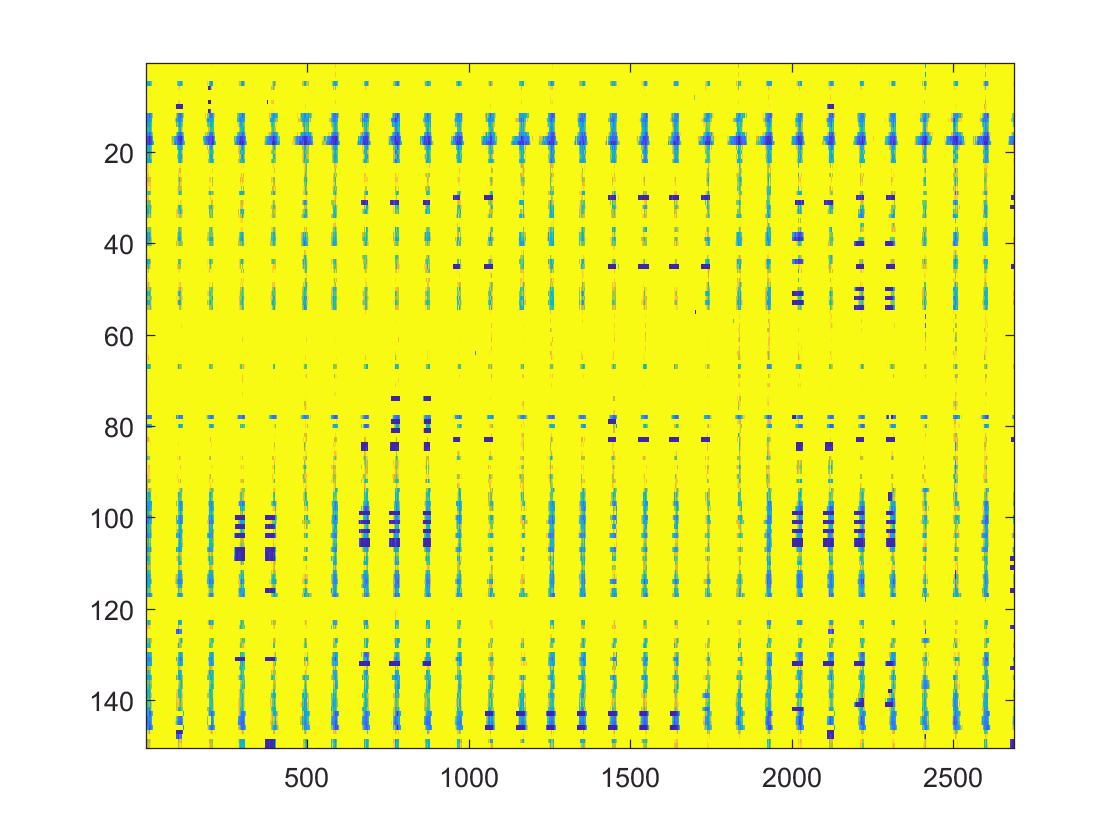

image(Tdd);

%% Learning Curve (this takes a while)
clf;

r=[];
for n = 1:40
[Tcpd,lambda,Tgen] = mycpd_TL(T1t,n);

Tcpd{4}=[Tcpd{4};mean(Tcpd{4},1);mean(Tcpd{4},1)];
Tcpdl = Tcpd;
Tcpdl{4}=Tcpdl{4}*diag(lambda);
Tgen = cpdgen(Tcpdl);
Td = T1 - Tgen;
Td(isnan(Td)) = 0;
Tdelta = reshape(Td,[150*96*7 4]);

T2 = T1(:);
T2 = T2(~isnan(T2));

r=[r;[n mean(Tdelta.^2)]];
end

Tmean = nanmean(T1(:,:,:,1:2),4);
T1mean = T1;
T1mean(:,:,:,1) = Tmean;
T1mean(:,:,:,2) = Tmean;
T1mean(:,:,:,3) = Tmean;
T1mean(:,:,:,4) = Tmean;
Td = T1 - Tmean;
Td(isnan(Td)) = 0;
Tdelta = reshape(Td,[150*96*7 4]);

T2 = T1(:);
T2 = T2(~isnan(T2));

rmean=sqrt(mean(Tdelta.^2))



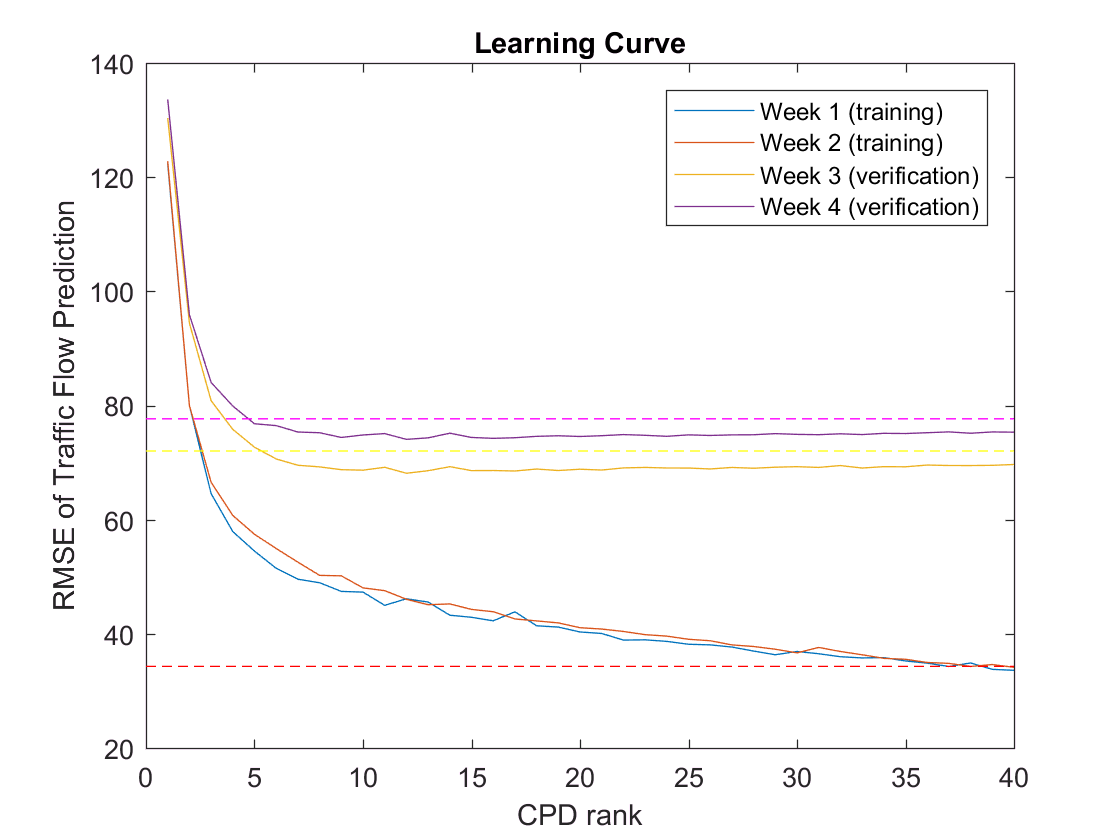

clf
hold off
plot([r(1:40,1)],[sqrt(r(1:40,2:end))],'-');
hold on
plot([0;r(40,1)],[rmean(1);rmean(1)],'--b');
%plot([0;r(40,1)],[rmean(2);rmean(2)],'--r');
plot([0;r(40,1)],[rmean(3);rmean(3)],'--y');
plot([0;r(40,1)],[rmean(4);rmean(4)],'--m');
hold off
title('Learning Curve');
legend({'Week 1 (training)','Week 2 (training)','Week 3 (verification)','Week 4 (verification)'});
xlabel('CPD rank');
ylabel('RMSE of Traffic Flow Prediction');